# Trabalho 5 - Projeto de controladores PID no domínio da frequência

## Nome: Gabrielly Barcelos Cariman

## Data limite para entrega: 24/11, 6h

**Importante lembrar:**

- Entrega após a data/horário acima: a nota será multiplicada por $1-e^{-30/h}$, onde h são as horas em atraso (Exemplo: 24h, multiplica por 0.71).

- O trabalho não é recebido por email

- Cabe a vocês garantir que o documento entregue é um arquivo pdf legível, e que não foi entregue com erro. Para isto, basta depositar e abrir para conferir.

- Código é apenas uma informação complementar, e não é considerada parte da solução para fins de avaliação.

- Caso não haja tempo de fazer todo o trabalho, entregue no prazo o que estiver pronto.

I=14; % Seu valor de I
[G, ts0, G1]=ini_t5(I)

G =
 
            24
  ----------------------
  217.8 s^2 + 39.6 s + 1
 
Continuous-time transfer function.
Model Properties


ts0 = 48.3000

G1 =
 
  24
  ---
  s^2
 
Continuous-time transfer function.
Model Properties


datetime('now')

ans = datetime
   24-Nov-2023 04:44:41


**Parte I: **Projete um controlador PI C1 que atenda:

- Erro nulo em regime para entrada degrau

- Tempo de estabelecimento $\le$ts0 segundos.

**Parte II: **Projete um controlador derivativo C2 de modo a obter um controlador PID=C1*C2 tal que as especificações anteriores sejam mantidas e adicionalmente se tenha

- Sobreelevação $\le$4%

- Tempo de estabelecimento menor que ts0

**Parte III: Estabilização: ** Usar critério de Nyquist para verificar se um controlador PD ou PI estabiliza G1(s)

**O que apresentar:**

Projeto do controlador PI (C1):

1) Gráfico de Bode de G e de C1G explicando a escolha do módulo adicionado, a localização do zero do PI, e as mudanças que o controlador C1 ocasionou nas margens de ganho e fase. Identifique a frequência de cruzamento de ganho por 0dB no gráfico de Bode com o controlador C1.

2) Resposta ao degrau em malha fechada e sinal de controle aplicado plotados no mesmo gráfico, mostrando o atendimento das especificações e explicitando os valores de Kp e Ki.

3) Resumir os passos do projeto do controlador PI (**Atenção: não são os comandos dados!**)

Projeto do controlador PD (C2):

4) Gráfico de Bode de C1G e de C1C2G identificando a localização do zero do PD, e as mudanças que o controlador C2 ocasionou na margem de fase em relação ao controlador C1G.

5) Resposta ao degrau em malha fechada mostrando o atendimento das especificações.

6) Sinal de controle devido ao controlador C1C2, explicitando o valor de Kd e o parâmetro Tf do filtro.

7) Resumir os passos do projeto do PD  (**Atenção: não são os comandos dados!**)

Estabilização:

8) Verifique via critério de Nyquist se um controlador PD estabiliza G1(s): Fazer o gráfico de Nyquist e aplicar o critério

9) Verifique via critério de Nyquist se um controlador PI estabiliza G1(s): Fazer o gráfico de Nyquist e aplicar o critério

## **Parte I: Projeto do PI (C1) **

- Erro nulo em regime para entrada degrau

- Tempo de estabelecimento $\le$ts0 segundos.

s = tf('s');
ts0

ts0 = 48.3000

G

G =
 
            24
  ----------------------
  217.8 s^2 + 39.6 s + 1
 
Continuous-time transfer function.
Model Properties


O controlador PI é dado por:


$$\textrm{C1}\left(s\right)=K_i \;\frac{1+\frac{K_p }{K_i }s}{s}$$


O controlador PI eleva o tipo do sistema ao adicionar um polo na origem. Assim, o erro à entrada de degrau torna-se nulo em qualquer sistema que emprega o controlador proporcional-integral (PI).

Por isso, o zero ficaria localizado em $\frac{K_p }{K_i }$ 

Assim, a fase será de $-90^o$ uma década antes de $\frac{K_i}{K_p}$, $-45^o$  em  $\frac{K_i}{K_p}$  e $0^o$ em $10\frac{K_i}{K_p}$, como mostrado na figura abaixo. 

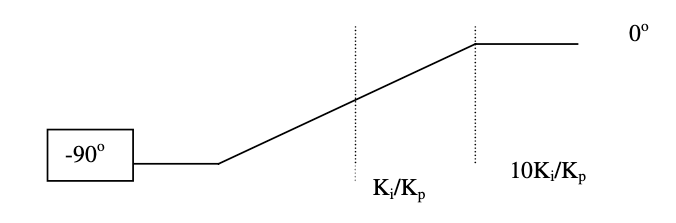					

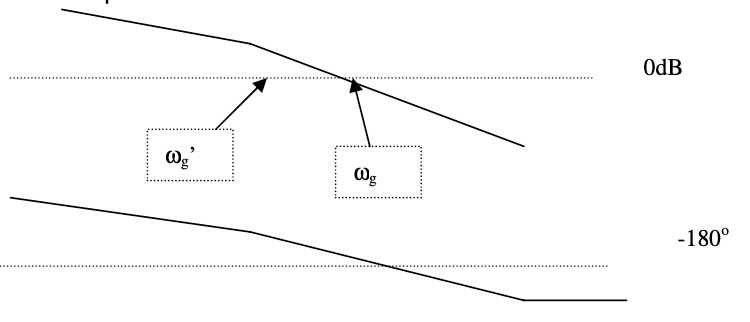			

Se o módulo de G(s) cruzasse em 0dB em $\omega_g^{'}$, a MF seria maior. Para que isto aconteça, basta escolher $K_p<1$ para abaixar a curva de módulo. Assim, escolhendo $K_p$ tal que 

$|G(j\omega_g^{'})|+20log_{10}K_p=0$    ou   $K_p=10^{- \frac{|G(j\omega_g^{'})|}{20}}$

O módulo da curva compensada cruzará em 0dB na nova frequência $\omega_g^{'}$

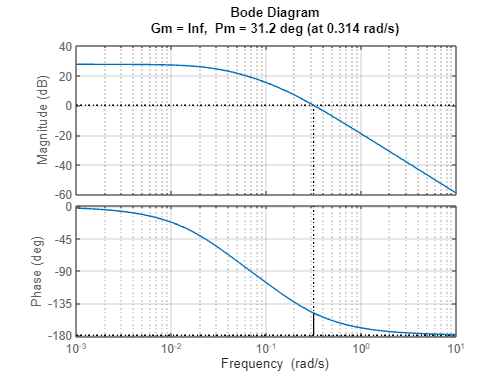

figure;margin(G);grid;

A margem de fase é 31.2 graus.

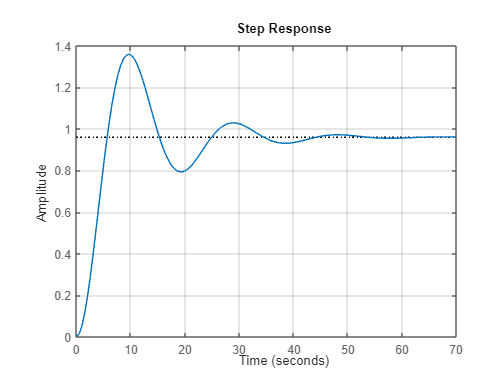

m=feedback(G,1);
figure;step(m);grid;

S = stepinfo(m);
[y,t]=step(m);
ts = round(S.SettlingTime, 1)

ts = 41.2000

erro = round(1-y(end), 1)

erro = 0

ts0

ts0 = 48.3000

A função G já atende as especificações de erro nulo em regime para entrada degrau e tempo de estabelecimento $\le$48.3 segundos.

Por isso, o ideal é realizar pequenas alterações na função para que ela continue a atender aos requisitos.

Ao analisar a resposta ao degrau de G, é possível observar que ela apresenta um elevado sobressinal (UP). Portanto, vamos tentar aumentar a margem de fase. Isso resultará em um sistema mais estável e, consequentemente, com menos oscilações e um menor sobressinal.

Para aumentar a MF para 38 graus. Para isto, a curva de módulo deve cruzar por 0 dB em $\omega_g^{'}=0,25rad/s$, implicando em uma redução do módulo de 5dB. Usando a expressão $K_p=10^{-\frac{|G(j\omega_g^{'})|}{20}}$, $K_p=10^{-\frac{5}{20}}$

wg = 0.25;
M = 5;
Kp = 10^(-M/20)

Kp = 0.5623

O zero do PI em $s=-\frac{K_i}{K_p}$ deve ser colocado uma década antes de $\omega_g^{'}$, portanto em $0,025 rad/s$.

Obtendo o valor de $K_i$:

Observando a curva de fase do controlador, na frequência $10\frac{K_i}{K_p}$ a fase devida ao controlador é zero graus.  Assim, escolhendo $10\frac{K_i}{K_p}=\omega_g^{'}$, a curva compensada de fase não sofrerá alteração na frequência $\omega_g^{'}$, onde queremos nossa nova e maior margem de fase. 

 Desse modo em $\omega_g^{'}=0,25rad/s$ o efeito do atraso de fase do controlador já tenha desaparecido. 

Portanto:


$$K_i = \frac{ \omega_g^{'} K_p}{10}$$


Ki = (wg*Kp)/10

Ki = 0.0141

C1=tf([Kp Ki],[1 0])

C1 =
 
  0.5623 s + 0.01406
  ------------------
          s
 
Continuous-time transfer function.
Model Properties


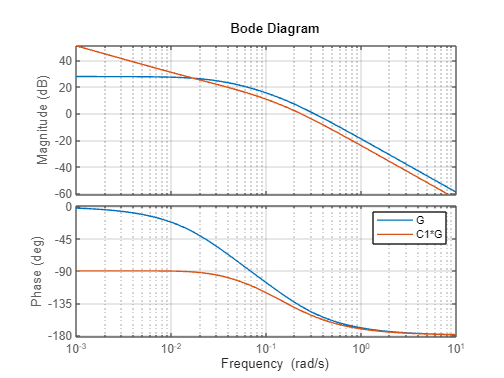

figure;
bode(G,C1*G);grid;legend('G', 'C1*G');

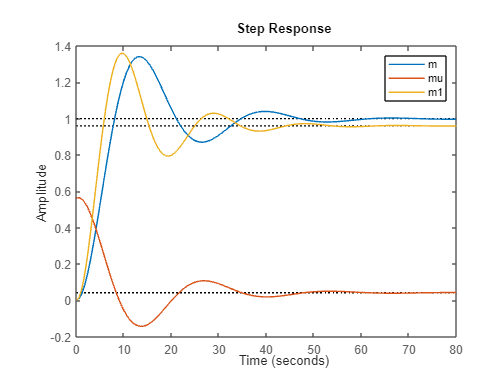

m=feedback(C1*G,1);
mu=feedback(C1,G);
m1=feedback(G,1);
figure;step(m,mu,m1);legend();

S = stepinfo(m);
[y,t]=step(m);
ts = round(S.SettlingTime, 1)

ts = 44.1000

erro = round(1-y(end), 1)

erro = 0

ts0

ts0 = 48.3000

A resposta atual atende às especificações, com um tempo de estabilização de 44,1 segundos que é $\le$48.3 segundos e tem erro nulo em regime para entrada degrau.

1) Gráfico de Bode de G e de C1G explicando a escolha do módulo adicionado, a localização do zero do PI, e as mudanças que o controlador C1 ocasionou nas margens de ganho e fase. Identifique a frequência de cruzamento de ganho por 0dB no gráfico de Bode com o controlador C1.

figure;
bode(G,C1*G);grid;legend('G', 'C1*G');

A frequência de cruzamento de ganho por 0dB no gráfico de Bode de G é de 0.3 rad/s e com o controlador C1 é de 0.2 rad/s. O controlador C1 faz essa frequência diminuir porque dessa forma é possível aumentar a margem de fase, tornar o sistema mais estável e com isso diminuir o UP. Essa função não toca o -180 no gráfico de fase, por isso, para os dois casos, a margem de ganho se manteve como infinito. Os valores das frequência de cruzamento de ganho por 0dB podem ser confirmados abaixo:

figure;margin(G);grid;

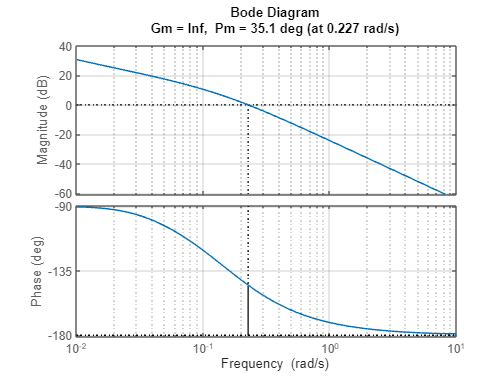

figure;margin(C1*G);grid;

2) Resposta ao degrau em malha fechada e sinal de controle aplicado plotados no mesmo gráfico, mostrando o atendimento das especificações e explicitando os valores de Kp e Ki.

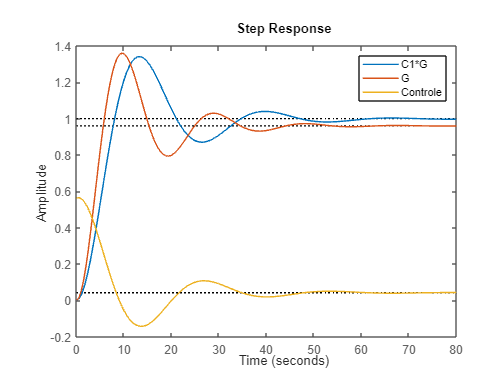

m=feedback(C1*G,1);
m1=feedback(G,1);
mu=feedback(C1,G);
figure;step(m,m1,mu);legend('C1*G', 'G', 'Controle');

S = stepinfo(m);
[y,t]=step(m);
ts = round(S.SettlingTime, 1)

ts = 44.1000

erro = round(1-y(end), 1)

erro = 0

ts0

ts0 = 48.3000

A resposta atual atende às especificações, com um tempo de estabilização de 44,1 segundos que é $\le$48.3 segundos e tem erro nulo em regime para entrada degrau. O gráfico com C1 oscila menos.

C1

C1 =
 
  0.5623 s + 0.01406
  ------------------
          s
 
Continuous-time transfer function.
Model Properties


Valores de Kp e Ki:

Kp = 0.5623

Ki = 0.01406

3) Resumir os passos do projeto do controlador PI:

- 1) Verifique se o controlador PI estabiliza o sistema e atende ao erro em regime permanente desejado.

- 2) Escolha o valor do ganho proporcional (Kp) de forma a satisfazer os requisitos de tempo de estabilização.

- 3) Trace o gráfico de Bode de $K_p G\left(s\right)$ e identifique a frequência de cruzamento de ganho: ${\omega_g }^{\prime }$

- 4) Calcule o valor de $K_i$ de forma que $K_i = \frac{ \omega_g^{'} K_p}{10}$

- 5) Verifique se as especificações são atendidas em relação aos critérios de desempenho estabelecidos.

## Parte II: Projeto do PD (C2)

- Sobreelevação $\le$4%

- Tempo de estabelecimento menor que ts0

O controlador PD é dado por $G_c(s)=K_p+K_ds=K_p(1+\frac{K_d}{K_p}s)$, isto é, um zero é adicionado em $s=-\frac{K_{p}}{K_d}$.

Portanto, o ganho Kp deve ser escolhido de forma a atender aos requisitos de erro em estado estacionário e tempo de estabelecimento, enquanto o ganho Kd deve ser ajustado para atender às condições de resposta transitória, especificadas em termos de margem de fase.

O ganho proporcional pode ser utilizado para atender a especificação de erro em regime. Como nesse caso a especificação já está atendida, o Kp será 1.

Por se tratar de um zero, seu efeito nas curvas de módulo e fase do gráfico de Bode são mostrados abaixo.

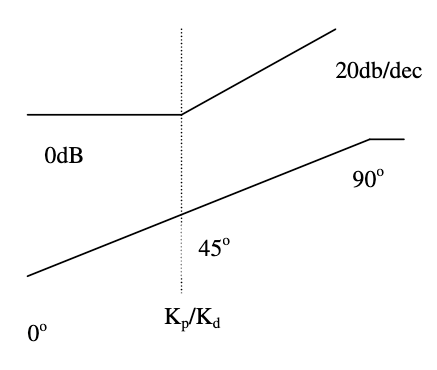

A partir da frequência do zero do PD, o módulo começa aumentar 20dB/década. Nesta frequência, a fase já avançou 45°.

Se o zero for colocado em $\omega_g^{'}$, o módulo não subirá nesta frequência e a fase subirá 45°, aumentando a margem de fase. Logo, variações em torno desta frequência permitirão obter a melhor MF possível. E ao aumentar a MF, diminui o UP que é o objtivo, porque o sistema se torna mais estável.

Voltando ao projeto do controlador PI, que resultou no controlador:

C1*G

ans =
 
      13.5 s + 0.3374
  ------------------------
  217.8 s^3 + 39.6 s^2 + s
 
Continuous-time transfer function.
Model Properties


Vamos incluir neste projeto o efeito do PD, com ganho proporcional do PD igual a 1, ou seja, usando apenas o ganho $K_d.$ Portanto, o zero é colocado em $s=-\frac{1}{K_d}$. Vamos começar com seu gráfico de Bode:

figure;margin(C1*G);grid;

Vamos aumentar a margem de fase de sistema com o controlador PD colocando um zero torno de $\omega_g=0.2rad/s$, ou seja, $\frac{1}{K_d}=0.2$      

Escolheremos $K_d=1/0.2$. Logo, o controlador PID será

Kp = 1;
wg = 0.2;
Kd = Kp/wg

Kd = 5

C2 = Kp*(1+((Kd/Kp)*s))

C2 =
 
  5 s + 1
 
Continuous-time transfer function.
Model Properties


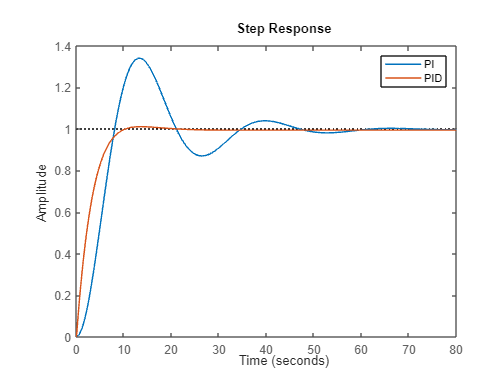

m1=feedback(C1*G,1);
m2=feedback(C2*C1*G,1);
figure;step(m1,m2);legend('PI','PID');

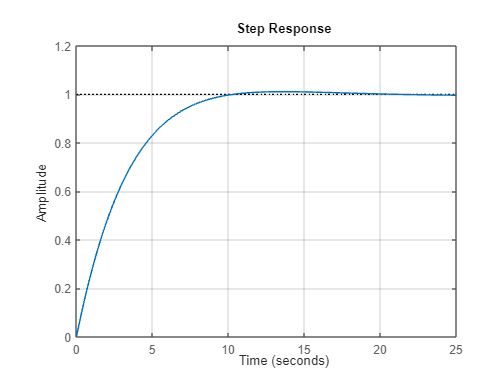

m=feedback(C2*C1*G,1);
figure;step(m2);grid;

S = stepinfo(m2);
[y,t]=step(m2);
up = round(S.Overshoot, 1)

up = 1.1000

ts = round(S.SettlingTime, 1)

ts = 8.7000

erro = round(1-y(end), 1)

erro = 0

ts0

ts0 = 48.3000

A resposta atual atende às especificações, com um tempo de estabilização de 8,7 segundos que é $\le$48.3 segundos, tem erro nulo em regime para entrada degrau e tem sobreelevação de 1.1% que é $\le$4%.

4) Gráfico de Bode de C1G e de C1C2G identificando a localização do zero do PD, e as mudanças que o controlador C2 ocasionou na margem de fase em relação ao controlador C1G.

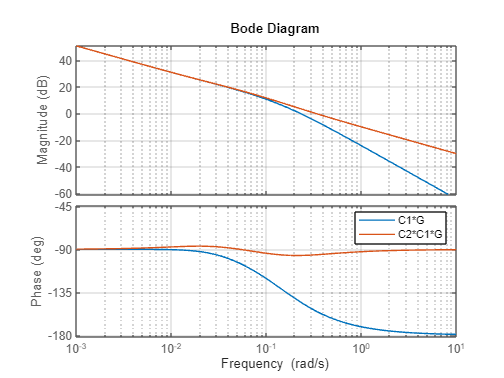

figure;
bode(C1*G,C2*C1*G);grid;legend('C1*G', 'C2*C1*G');

O controlador C2*C1 aumentou a margem de fase ao adicionar o zero, tornar o sistema mais estável e com isso diminuir o UP. Essa função não toca o -180 no gráfico de fase, por isso, para os dois casos, a margem de ganho se manteve como infinito.

Como, na frequência do zero do PD, a fase já avançou 45°, é possível perceber no gráfico de C2*C1*G e comparando com C1*G que em 0.2rad/s tem um zero localizado.

5) Resposta ao degrau em malha fechada mostrando o atendimento das especificações

e

6) Sinal de controle devido ao controlador C1C2, explicitando o valor de Kd e o parâmetro Tf do filtro

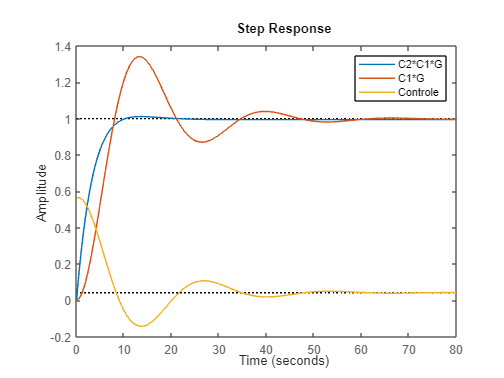

m=feedback(C2*C1*G,1);
m1=feedback(C1*G,1);
mu=feedback(C1,G);
figure;step(m,m1,mu);legend('C2*C1*G', 'C1*G', 'Controle');

S = stepinfo(m);
[y,t]=step(m);
ts = round(S.SettlingTime, 1)

ts = 8.7000

erro = round(1-y(end), 1)

erro = 0

up = round(S.Overshoot, 1)

up = 1.1000

ts0

ts0 = 48.3000

A resposta atual atende às especificações, com um tempo de estabilização de 8,7 segundos que é $\le$48.3 segundos, tem erro nulo em regime para entrada degrau e tem sobreelevação de 1.1% que é $\le$4%.

Valores de Kp e Kd:

Kp

Kp = 1

Kd

Kd = 5

O parâmetro Tf do filtro precisa ser utilizado para que o PD seja realizável. Pelo fato que ele adiciona um zero a função sem adicionar um polo.

Ao adicionar o zero na função, ela pode ficar com mais zeros do que polos. Dessa forma, ela não será causal. Portanto, não será realizável.

Assim, um polo deve ser adicionado, que tem a função de filtro, $G_c(s)=K_p+K_d\frac{s}{T_fs+1}$. 

Porém esse não é o caso da função G, foi possível adicionar o zero do PD e a função ainda é realizável.

Por isso, o parâmetro Tf do filtro não foi adicionado não sendo necessário.

7) Resumir os passos do projeto do PD

- 1) Avalie se o controlador PD é capaz de estabilizar o sistema.

- 2) Verifique se o controlador PD atende aos requisitos de erro em regime permanente estabelecidos.

- 3) Confira se o controlador PD é capaz de atender à margem de fase especificada.

- 4) Determine o valor adequado para o ganho proporcional Kp, de modo a cumprir as condições de erro em regime e/ou tempo de estabilização.

- 5) Construa o gráfico de Bode para KpG(s).

- 6) Coloque o zero do controlador PD $\left(s=-\frac{K_p }{K_d }\right)$ próximo à frequência de cruzamento de ganho,$\omega_g$, (0 dB).

- 7) Varie a posição do zero do PD para atender aos critérios de margem de fase desejada ou sobressinal desejado, conforme avaliado por meio de simulação.

## Parte III: Estabilização

Fazer os gráficos de Nyquist (à mão ou no Matlab) e aplicar o critério

Usar critério de Nyquist para verificar se um controlador PD ou PI estabiliza G1(s)

8) Verifique via critério de Nyquist se um controlador PD estabiliza G1(s): Fazer o gráfico de Nyquist e aplicar o critério

s = tf('s');
G1

G1 =
 
  24
  ---
  s^2
 
Continuous-time transfer function.
Model Properties


Vamos verificar se o sistema é estável ou instável usando o critério de Nyquist.

O critério de estabelildade de Nyquist é dado por: $\phi =\left(Z_d -P_d -\;\frac{P_w }{2}\right)*180$

Em que:

Zd são os zeros no SPD em malha fechada

Pw são os polos na origem em malha aberta

Pd são os polos no SPD em malha aberta

$\phi$ é o ângulo da função em torno do ponto -1 quando a frequência varia de infinito a zero.

Portanto, para calcular o $\phi$ para que o sistema seja estável, temos:

Zd = 0;
Pw = 2;
Pd = 0;
phi = (Zd - Pd - (Pw/2))*180

phi = -180

Analisando a função G1 e sabendo que o zero avança a fase 90 graus e o polo atrasa a fase -90 graus. Como G1 tem 2 polos na origem, a sua fase é constatemente -180 graus. O ângulo $\phi$ é o ângulo da função em torno do ponto -1 que é de zero graus, por manter constante o valor de fase de -180 graus, como pode ser observado no gráfico abaixo.

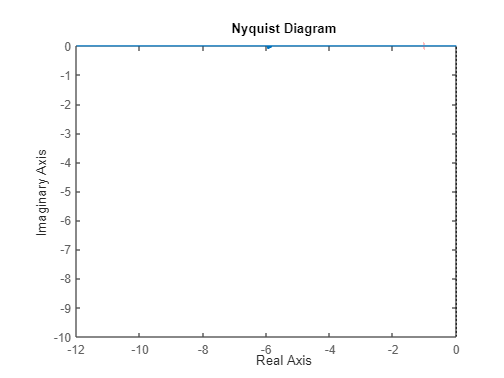

h=nyquistplot(G1);
set(h,'ShowFullContour','off')

Como zero graus, do ângulo $\phi$,  difere de -180 graus, é possível concluir, com base no critério de Nyquist, que o sistema não é estável. A resposta ao degrau em MF também confirma a instabilidade do sistema.

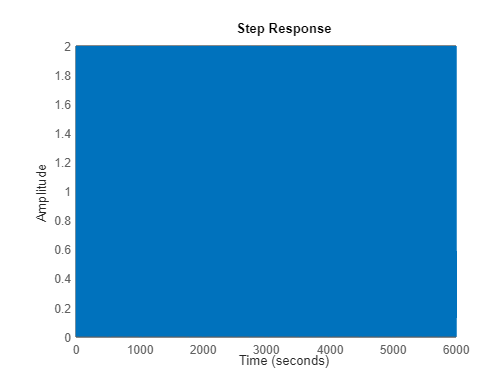

step(feedback(G1,1))

O controlador PD é dado por $G_c(s)=K_p+K_ds$, ou seja, um zero é adicionado a função de transferência.

Como esse zero será adicionado ao SPE para manter o sistema estável, existe apenas uma posição em que o zero pode ser colocado, a qual afetaria o valor de $\phi$ calculado pelo critério de estabilidade de Nyquist, e essa posição é quando o zero está localizado na origem.

Nessa situação, o zero irá anular um polo, resultando em uma função com apenas um polo na origem. O novo cálculo de estabilidade seria o seguinte:

Zd = 0;
Pw = 1;
Pd = 0;
phi = (Zd - Pd - (Pw/2))*180

phi = -90

$\phi$ = -90 graus é o $\phi$ para que o sistema seja estável

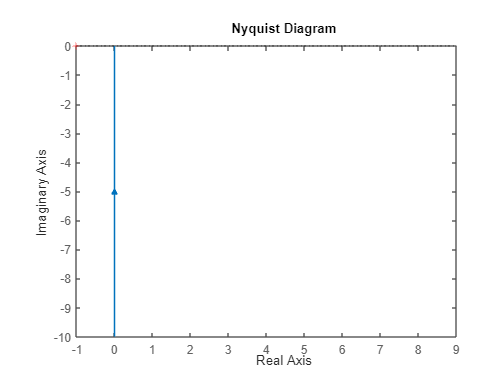

ft = G1*(s);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

Analisando o gráfico, é possível observar que ele é capaz de alcançar um ângulo de -90 graus com o zero localizado na origem.

A resposta ao degrau em malha fechada (MF) comprova que o sistema é estável.

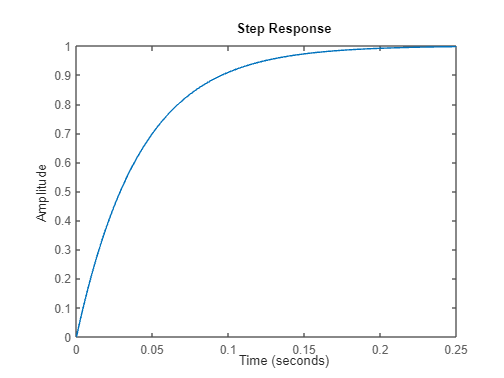

step(feedback(ft,1))

No entanto, se for aplicado um ganho Kp negativo, o ângulo será de +90 graus, o que tornará o sistema instável. Como pode ser observado abaixo:

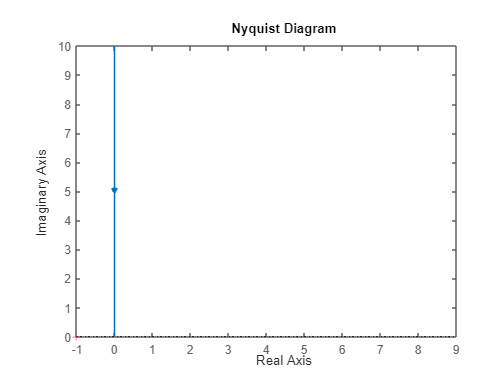

ft = G1*(s)*(-1);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

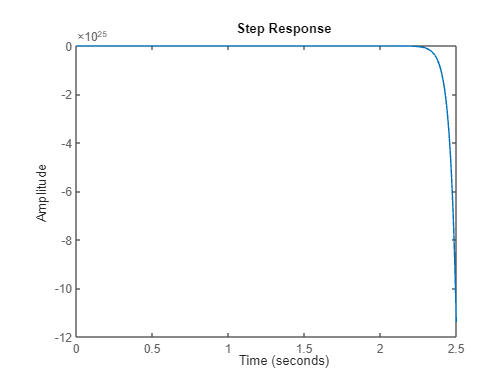

step(feedback(ft,1))

Para todos os outros casos, o ângulo $\phi$ permanece constante em -180 graus. Os gráficos começam em -180 graus devido à presença de dois polos e atingem -90 graus devido ao zero, que avança a fase em 90 graus. Portanto, o ângulo da função em torno do ponto -1, à medida que a frequência varia de infinito a zero, será sempre de -180 graus, independentemente do valor do ganho e local do zero, seja grande ou pequeno, como pode ser observado abaixo.

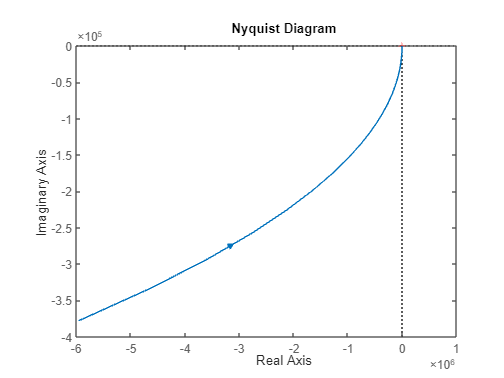

ft = G1*(s+0.001);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

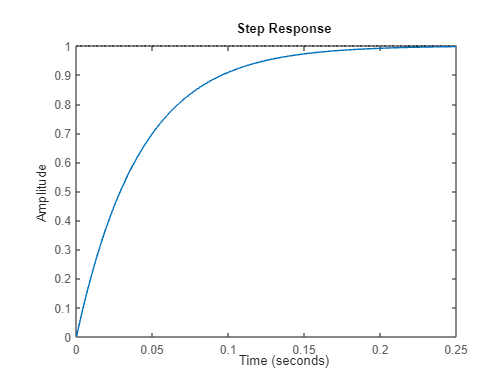

step(feedback(ft,1))

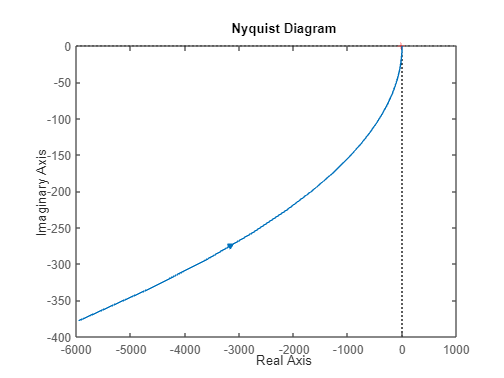


ft = G1*(s+1);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

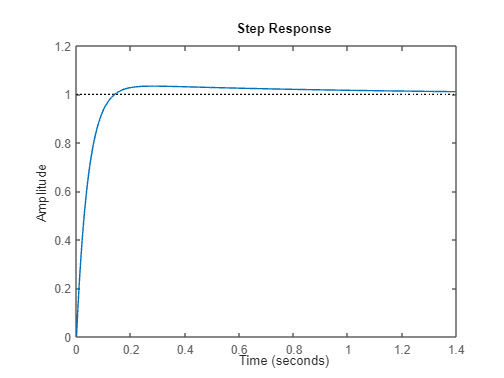

step(feedback(ft,1))

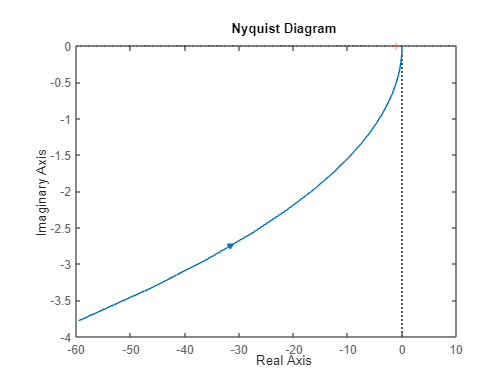


ft = G1*(s+100);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

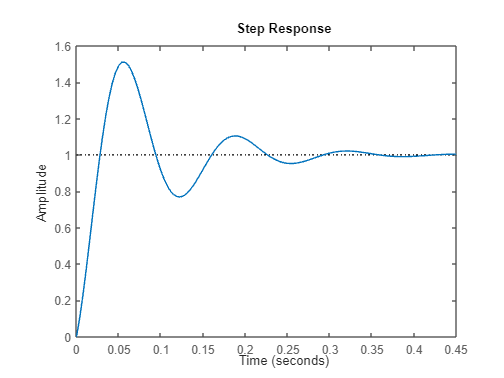

step(feedback(ft,1))

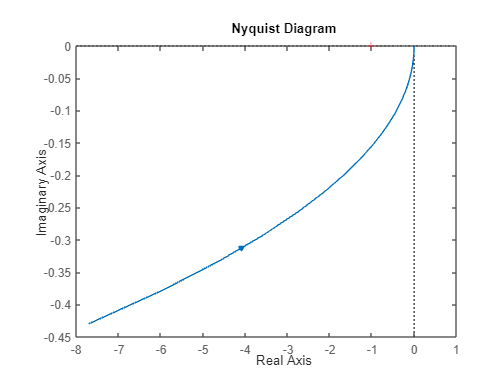


ft = G1*(s+1)*0.001;
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

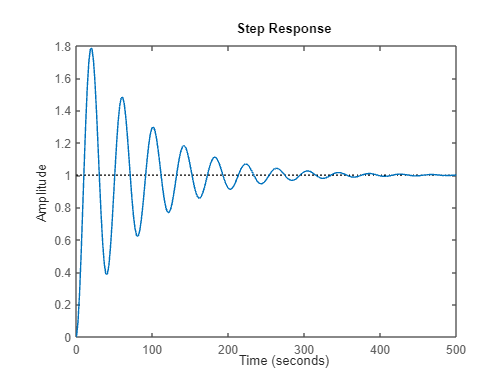

step(feedback(ft,1))

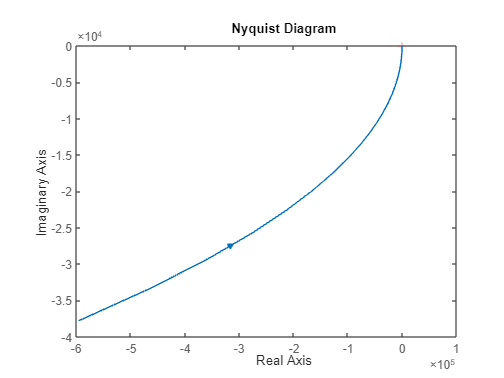


ft = G1*(s+1)*100;
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

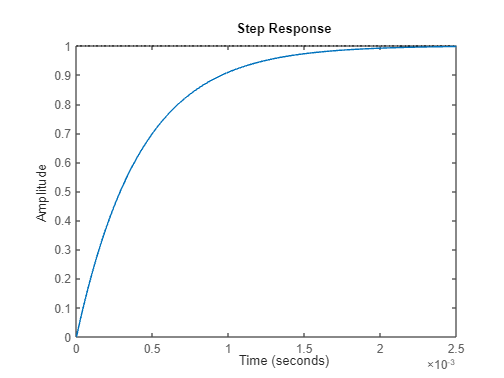

step(feedback(ft,1))

No entanto, ganhos negativos têm o modificam o ângulo $\phi$, resultando em um valor diferente de -180 graus. Fazendo com que a função não seja estável.

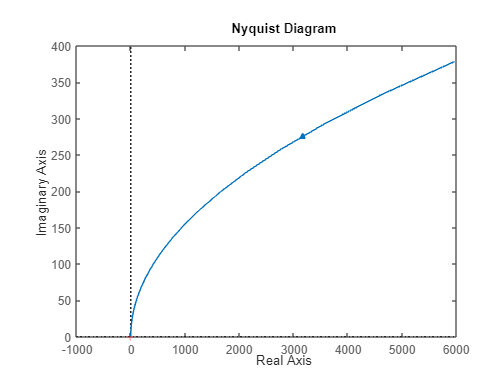

ft = G1*(s+1)*(-1);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

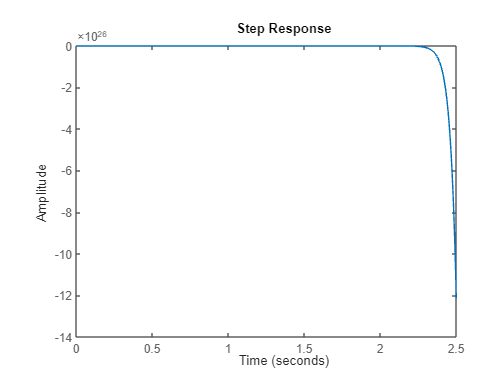

step(feedback(ft,1))

Portanto, o controlador PD estabiliza G1(s).

9) Verifique via critério de Nyquist se um controlador PI estabiliza G1(s): Fazer o gráfico de Nyquist e aplicar o critério

s = tf('s');
G1

G1 =
 
  24
  ---
  s^2
 
Continuous-time transfer function.
Model Properties


Vamos verificar se o sistema é estável ou instável usando o critério de Nyquist.

O critério de estabelildade de Nyquist é dado por: $\phi =\left(Z_d -P_d -\;\frac{P_w }{2}\right)*180$

Em que:

Zd são os zeros no SPD em malha fechada

Pw são os polos na origem em malha aberta

Pd são os polos no SPD em malha aberta

$\phi$ é o ângulo da função em torno do ponto -1 quando a frequência varia de infinito a zero.

O controlador PD é dado por $G_c(s)=K_p\frac{s+\frac{K_i}{K_p}}{s}$, ou seja, um polo na origem e um zero são adicionados a função de transferência.

Como foi adicionado um polo na origem, o cálculo da estabilidade seria o seguinte:

Zd = 0;
Pw = 3;
Pd = 0;
phi = (Zd - Pd - (Pw/2))*180

phi = -270

Como esse zero será adicionado ao SPE para manter o sistema estável, existe apenas uma posição em que o zero pode ser colocado, a qual afetaria o valor de $\phi$ calculado pelo critério de estabilidade de Nyquist, e essa posição é quando o zero está localizado na origem.

Nessa situação, o zero irá anular um polo, resultando em uma função original G1 que tem dois polos na origem. O novo cálculo de estabilidade seria o seguinte:

Zd = 0;
Pw = 2;
Pd = 0;
phi = (Zd - Pd - (Pw/2))*180

phi = -180

$\phi$ = -180 graus é o $\phi$ para que o sistema seja estável

ft = G1*(s)*(1/s);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

Analisando o gráfico e como mencionado anteriormente, esta função não é estável devido ao ângulo $\phi$  igual a zero graus, em vez do ângulo esperado de -180 graus.

A resposta ao degrau em malha fechada (MF) comprova que o sistema não é estável.

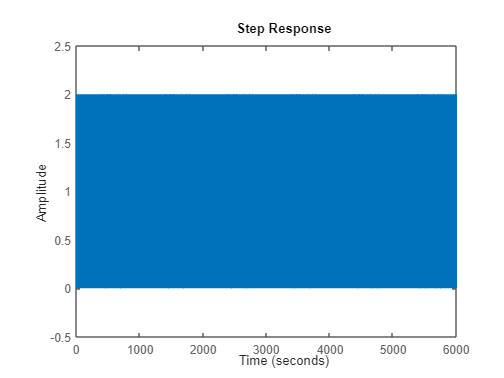

step(feedback(ft,1))

Se for aplicado um ganho Kp negativo, o ângulo será de 0 graus, também tornará o sistema instável. Como pode ser observado abaixo:

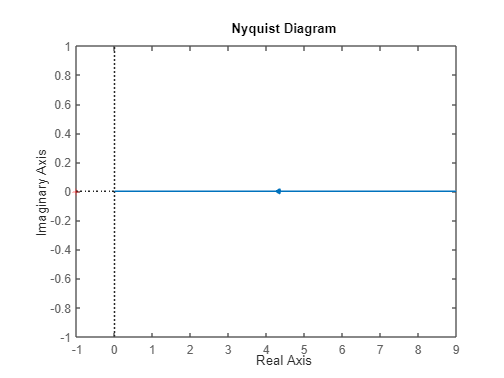

ft = G1*(s)*(1/s)*(-1);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

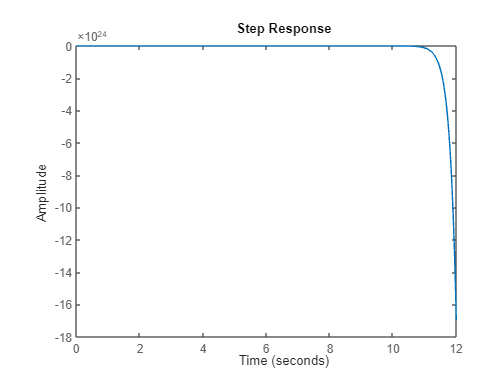

step(feedback(ft,1))

Para todos os outros casos, o ângulo $\phi$ permanece constante em -270 graus. Os gráficos começam em -270 graus devido à presença de três polos e atingem -180 graus devido ao zero, que avança a fase em 90 graus. Portanto, o ângulo da função em torno do ponto -1, à medida que a frequência varia de infinito a zero, nunca será -270 graus, independentemente do valor do ganho e local do zero, seja grande ou pequeno, como pode ser observado abaixo.

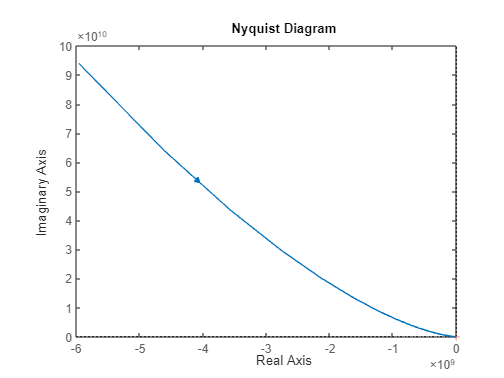

ft = G1*(s+0.001)*(1/s);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

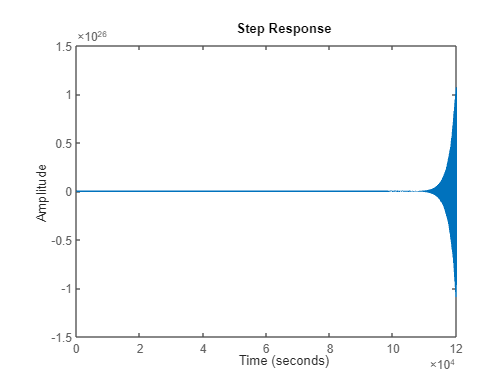

step(feedback(ft,1))

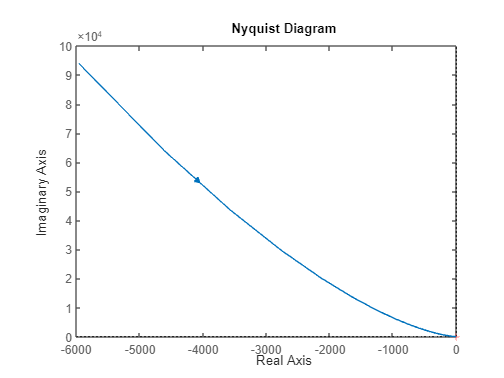


ft = G1*(s+1)*(1/s);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

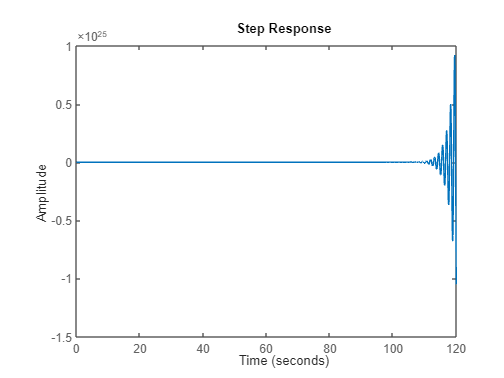

step(feedback(ft,1))

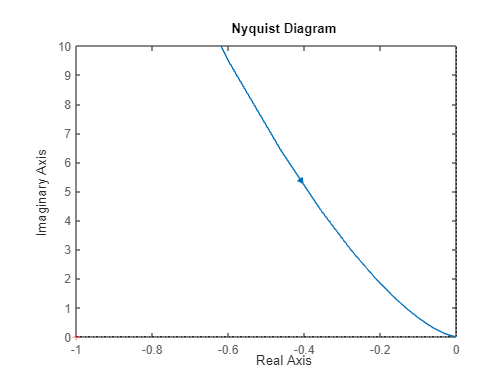


ft = G1*(s+100)*(1/s);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

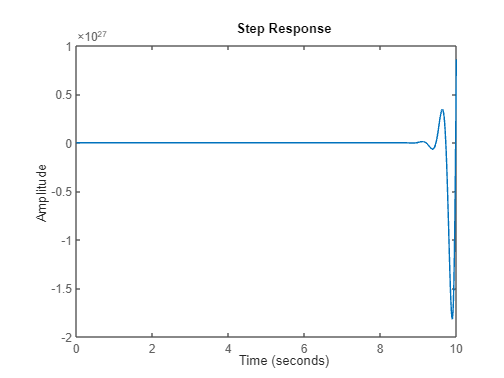

step(feedback(ft,1))

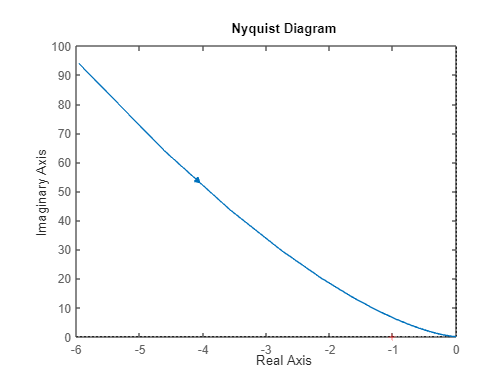


ft = G1*(s+1)*(1/s)*0.001;
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

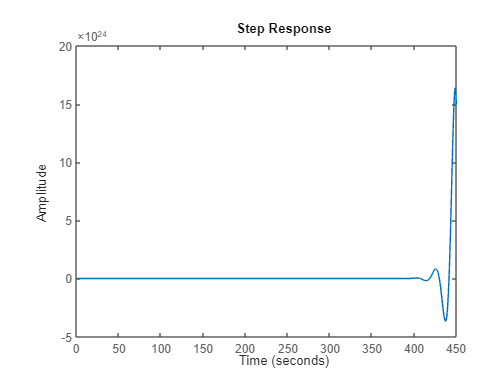

step(feedback(ft,1))

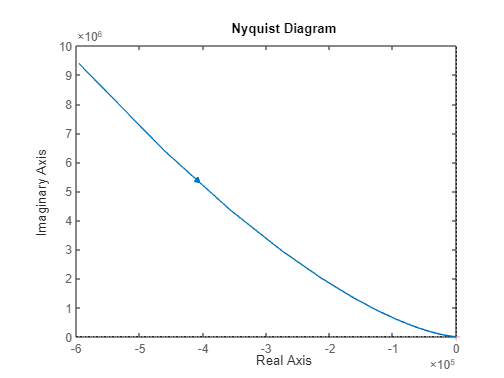


ft = G1*(s+1)*(1/s)*100;
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

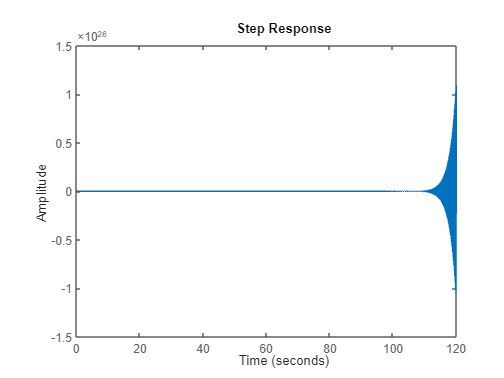

step(feedback(ft,1))

Ganhos negativos também modificam o ângulo $\phi$, resultando em um valor diferente de -270 graus. Fazendo com que a função não seja estável.

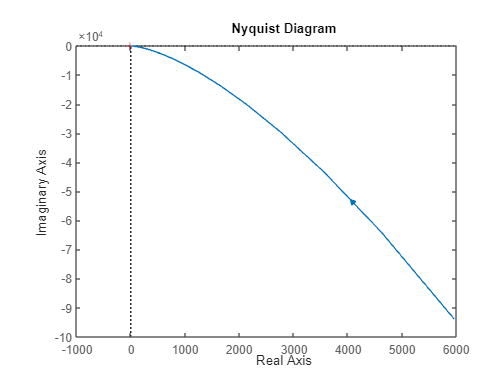

ft = G1*(s+1)*(1/s)*(-1);
h=nyquistplot(ft);
set(h,'ShowFullContour','off')

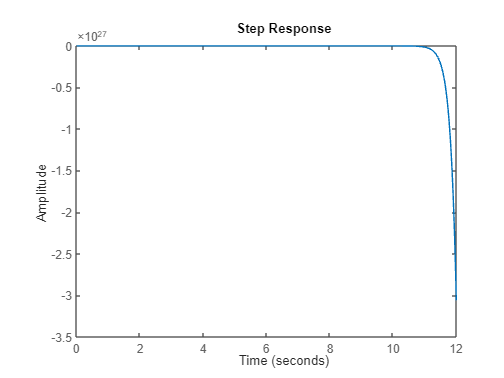

step(feedback(ft,1))

Portanto, o controlador PI não estabiliza G1(s).